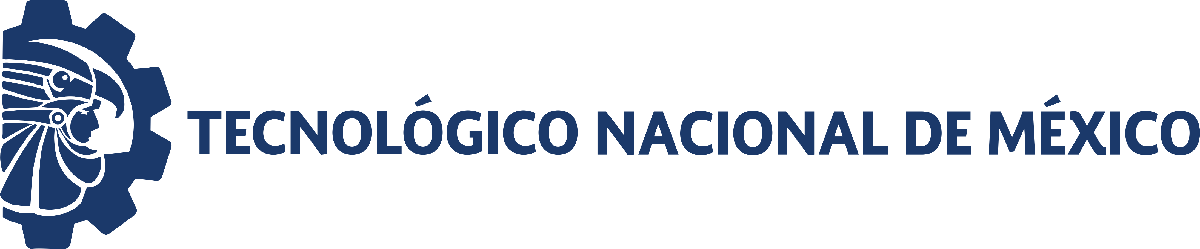                                 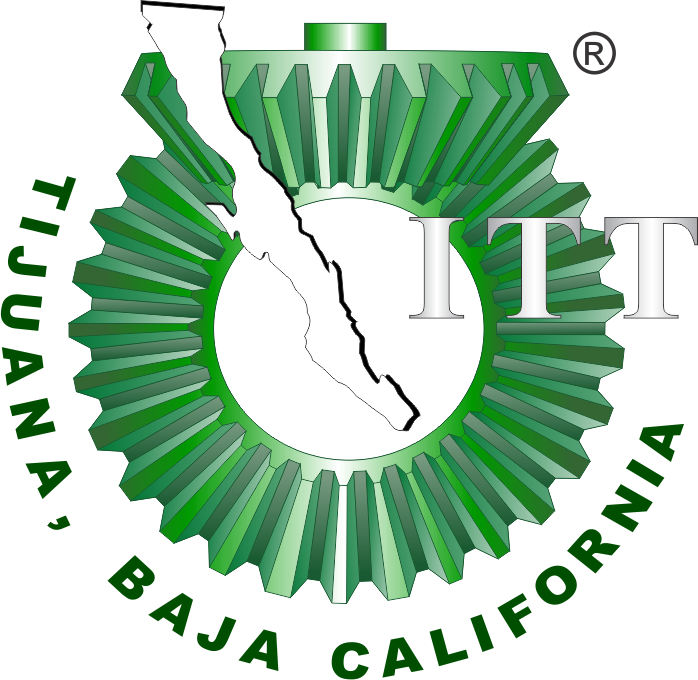

# Práctica 4: Modelizada matemático

# **Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: **Mendivil Ramirez Frida Daniela**

Número de control: **20211983**

Correo institucional: **L20211983@tectijuana.edu.mx**

Carrera: **Ingeniería Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Objetivo **

Construir y analizar un modelo mecanicista sobre de la dinámica entre dos variables biológicas.

## Algoritmo de regresión no lineal 

## 
$$\dot{x} =\rho_1 x\left(1-\frac{x+\gamma_1 y}{\beta }\right)$$


## 
$$\dot{y} =\rho_2 y\left(1-\frac{y+\gamma_2 x}{\beta }\right)$$


## 
$$\beta =10$$


### **Experimental data**

clc; clear; close all
sys = readmatrix('data.csv');
to = round(sys(:,1));
xo = sys(:,2); yo = sys(:,3); 
T = array2table([to,xo,yo],'VariableNames',{'Time', 'x(o): Biological variable', 'y(o): Biological variable'}); disp (T)

    Time    x(o): Biological variable    y(o): Biological variable
    ____    _________________________    _________________________

      0              0.83086                      0.99501         
      5                1.662                       2.5145         
     10               2.2956                       4.8358         
     15                2.837                       6.9758         
     20               3.9255                       6.9853         
     25               3.9262                       7.2348         
     30               4.7409                       6.7614         
     35               4.5751                       6.3823         
     40               5.2588                       6.3545         
     45               5.1664                       6.1724         
     50               5.8318                       6.0549         
     55                6.0

#### Function Data x(t)

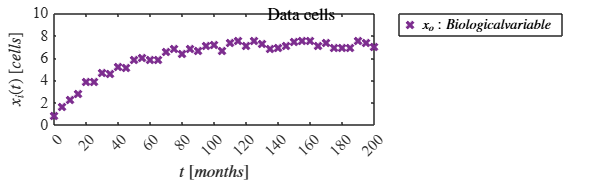

figure();
set(gcf, 'Color', 'w', 'Units', 'Centimeters', 'Position', [2,2,40,12])
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'FontUnits', 'points')

hold on; box on; grid off;
plot(to, xo, 'x', 'LineWidth', 2, 'Color', [0.49, 0.18, 0.56])  % Morado
xlabel('$t$ $[months]$','Interpreter', 'latex')
ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex')
L = legend('$x_o: Biological variable$','Interpreter', 'Latex', 'Location', 'NorthEastOutside');
set(L, 'FontSize', 9)
xlim([0 200]); xticks(0:20:200)
ylim([0 10]); yticks (0:2:10)
ttl = 'Data cells'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'Data_x.pdf', 'ContentType', 'vector')

#### Function Data y(t)

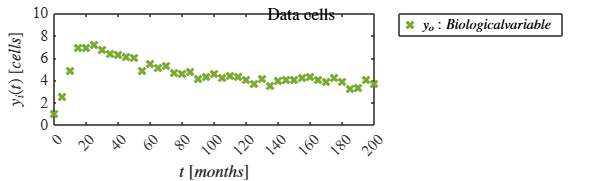

figure();
set(gcf, 'Color', 'w', 'Units', 'Centimeters', 'Position', [2,2,40,12])
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'FontUnits', 'points')

hold on; box on; grid off;
plot(to, yo, 'x', 'LineWidth', 2, 'Color', [0.47, 0.67, 0.19])  
xlabel('$t$ $[months]$','Interpreter', 'latex')
ylabel('$y_i(t)$ $[cells]$', 'Interpreter', 'latex')
L = legend('$y_o: Biological variable$','Interpreter', 'Latex', 'Location', 'NorthEastOutside');
set(L, 'FontSize', 9)
xlim([0 200]); xticks(0:20:200)
ylim([0 10]); yticks (0:2:10)
ttl = 'Data cells'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'Data_y.pdf', 'ContentType', 'vector')

### Model 

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0)


Sample size (n): 41
Parameters to be estimated (pars): 4
Degrees of freedom: 78
Significance level (alpha): 0.05
t-Student value:1.9908
Adjusted R-squared:0.97322
Corrected AIC (n/pars < 40):24.8386

    Parameters    Estimate       SE          MoE              CI95             pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265      0.005386    0.010723    0.14193    0.16337    8.0673e-43
      gamma1      0.67149      0.012893    0.025668    0.64582    0.69716    2.3483e-62
      rho2        0.27412      0.011137    0.022173    0.25195     0.2963    1.6218e-38
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371    9.9945e-84



mdl = Nonlinear regression model:
    y ~ variant/model(b,X)

Estimated Coefficients:
          Estimate       SE        tStat       pValue  
          ________    _________    ______    __________

    b1    0.15265      0.005386    28.342    8.0673e-43
    b2    0.67149      0.012893    52.081    2.3483e-62
    b3    0.27412      0.011137    24.613    1.6218e-38
    b4    0.82706     0.0083655    98.865    9.9945e-84


Number of observations: 82, Error degrees of freedom: 78
Root Mean Squared Error: 0.275
R-Squared: 0.974,  Adjusted R-Squared 0.973
F-statistic vs. zero model: 8.54e+03, p-value = 3.49e-102

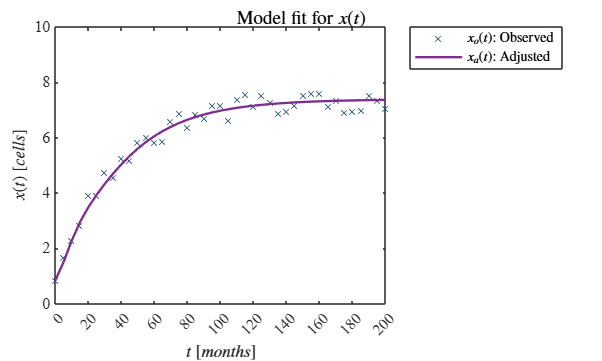

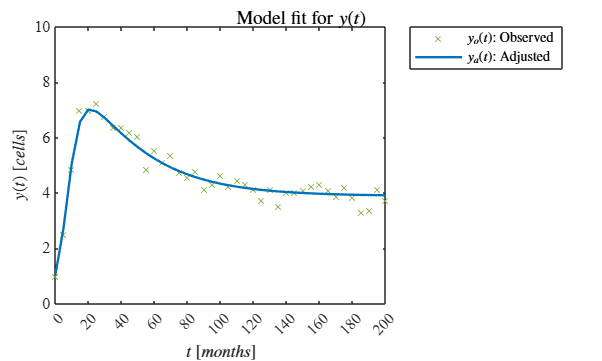

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P);

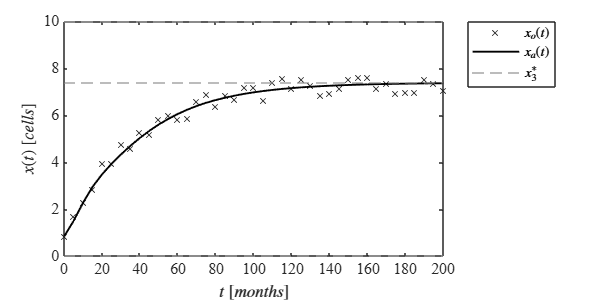

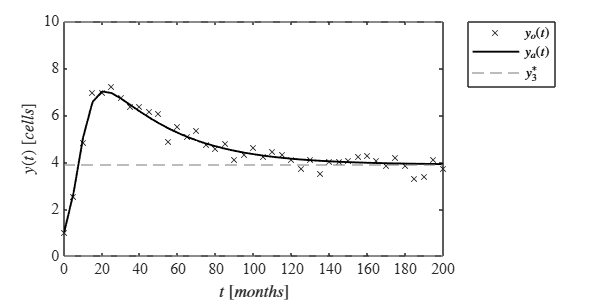

plotEquilibria(to, [xo,xa], [yo,ya], P);

### Jacobanian matrix

   clear all; 
    syms x y rho1 gamma1 rho2 gamma2 beta
    dx= rho1*x*(1 - (x+gamma1*y)/beta);
    dy = rho2*y*(1 - (y+gamma2*x)/beta);    
    J = jacobian([dx,dy],[x,y]);
    fprintf('Jacobian matrix of the system'); disp(J)

Jacobian matrix of the system

$$\left(\begin{array}{cc} -\rho_{1}\,\left(\frac{x+\gamma_{1}\,y}{\beta }-1\right)-\frac{\rho_{1}\,x}{\beta } & -\frac{\gamma_{1}\,\rho_{1}\,x}{\beta }\\ -\frac{\gamma_{2}\,\rho_{2}\,y}{\beta } & -\rho_{2}\,\left(\frac{y+\gamma_{2}\,x}{\beta }-1\right)-\frac{\rho_{2}\,y}{\beta } \end{array}\right)$$

    dx= rho1*x*(1 - (x+gamma1*y)/beta)== 0;
    dy = rho2*y*(1- (y+gamma2*x)/beta)== 0; 
    edos = solve([dx,dy],[x,y]);
    fprintf(['The system has ', num2str(length(edos.x)), ' equilibrium points.'])

The system has 4 equilibrium points.

    X0= edos.x(1); Y0 =edos.y(1);
    X1= edos.x(2); Y1 =edos.y(2);
    X2= edos.x(3); Y2 =edos.y(3);
    X3= edos.x(4); Y3 =edos.y(4);
    syms x0 y0 x1 y1 x2 y2 x3 y3
    fprintf('Equilibrium points of the system:');...
        disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1]); disp([x2,y2,X2,Y2]); disp([x3,y3,X3,Y3]);

Equilibrium points of the system:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \beta & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{2} & y_{2} & 0 & \beta \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{3} & y_{3} & \frac{\beta \,\left(\gamma_{1}-1\right)}{\gamma_{1}\,\gamma_{2}-1} & \frac{\beta \,\left(\gamma_{2}-1\right)}{\gamma_{1}\,\gamma_{2}-1} \end{array}\right)$$


    clear rho1 gamma1 rho2 gamma2 beta
    rho1 = 0.15265;
    gamma1 = 0.67149;
    rho2 = 0.27411;
    gamma2 = 0.82706;
    beta = 10;
    disp('(x0,y0) = (0,0)');...
        disp (['(x1,y1) = (', num2str(beta), ',', num2str(0),')'])

(x0,y0) = (0,0)


(x1,y1) = (10,0)


        disp (['(x2,y2) = (', num2str(0), ',', num2str(beta),')'])

(x2,y2) = (0,10)


        disp (['(x3,y3) = (', num2str(((beta*(gamma1-1))/((gamma1*gamma2)-1))), ',', num2str(((beta*(gamma2-1))/((gamma1*gamma2)-1))),')'])

(x3,y3) = (7.3883,3.8895)


### Local stability

    clc; clear;
    rho1 = 0.15265; gamma1 = 0.67149;
    rho2 = 0.27411;  gamma2 = 0.82706;
    beta = 10;
    syms x y
    dx= rho1*x*(1 - (x+gamma1*y)/beta)== 0;
    dy = rho2*y*(1- (y+gamma2*x)/beta)== 0; 
    edos = solve ([dx,dy],[x,y]);
    x0 = double(edos.x(1)); y0= double(edos.y(1));
    x1 = double(edos.x(2)); y1= double(edos.y(2));
    x2 = double(edos.x(3)); y2= double(edos.y(3));
    x3 = double(edos.x(4)); y3= double(edos.y(4));
    clear x y
    x = [x0;x1;x2;x3]; y= [y0;y1;y2;y3];
    var= {'(x0,y0)'; '(x1,y1)'; '(x2,y2)'; '(x3,y3)'};
    Equilibria = table(x,y,'RowNames',var);
    Equilibria.Properties.VariableNames= {'xe','ye'};
    fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
                 xe        ye  
               ______    ______

    (x0,y0)         0         0
    (x1,y1)        10         0
    (x2,y2)         0        10
    (x3,y3)    7.3883    3.8895



    L= zeros(2,2)

L =      0     0
     0     0


    for i = 1:length(x)
        J = [-rho1*((((x(i) + gamma1*y(i))/beta) - 1) - (rho1*x(i)/beta)),                  (gamma1*rho1*x(i)/beta);
             (gamma2*rho2*y(i)/beta),             -rho2*((((y(i) + gamma2*x(i))/beta) - 1) - (rho2*y(i)/beta)) ]
        L(i,:) = eig(J);
    end

J =     0.1527         0
         0    0.2741


J =     0.0233    0.1025
         0    0.0474


J =     0.0501         0
    0.2267    0.0751


J =     0.0172    0.0757
    0.0882    0.0292


    L1 = L(:,1); L2 = L(:,2);
    Lambdas = table(L1,L2,'RowNames',var);
    disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                  L1           L2   
               _________    ________

    (x0,y0)      0.15265     0.27411
    (x1,y1)     0.023302    0.047405
    (x2,y2)     0.075136    0.050147
    (x3,y3)    -0.058718     0.10516



### Functions

function mdl = variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

        function fi = model(P0,t)
        rho1 = P0(1); gamma1 = P0(2); rho2 = P0(3); gamma2 = P0(4);
        beta = 10;
        dt = 1E-1;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        
        for i = 1:n
        [fx,fy] = f(x(i), y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt; 
        [fxn,fyn] = f(xn,yn);
    
        x(i+1) = x(i) + (fx+fxn)*dt/2;
        y(i+1) = y(i) + (fy+fyn)*dt/2;
        end

        function [dx,dy]=f(x,y)
            dx= rho1*x*(1 - (x+gamma1*y)/beta);
            dy = rho2*y*(1- (y+gamma2*x)/beta);
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j)= x(k);
            yi(j)= y(k);
        end
        fi = [xi;yi];
    end
       mdl = fitnlm(to,fo,@model,P0);

       Estimate = table2array(mdl.Coefficients(:,1));
       SE = table2array(mdl.Coefficients(:,2));
       pvalue = table2array(mdl.Coefficients(:,4));
       alpha = 0.05;
       CI95 = coefCI(mdl,alpha);
       dof = mdl.DFE;
       tval = tinv(1 - alpha/2,dof);
       MoE = SE*tval;
       Parameters = ['rho1  ';'gamma1';'rho2  ';'gamma2'];
       Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

       fprintf(['\nSample size (n): ', num2str(numel(xo))])
       fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
       fprintf(['\nDegrees of freedom: ', num2str(dof)])
       fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
       fprintf(['\nt-Student value:', num2str(tval)])
       fprintf(['\nAdjusted R-squared:', num2str(mdl.Rsquared.Adjusted)])
       fprintf(['\nCorrected AIC (n/pars < 40):', num2str(mdl.ModelCriterion.AIC), '\n\n'])
       disp(Results)
end

### Plot model fit

function plotResults(to, x, y, P)
    %% Gráfica para x
    figure('Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,12])
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off
    plot(to, x(:,1), 'x', 'MarkerSize', 5, 'Color', [0.11, 0.30, 0.42]) % Observado
    plot(to, x(:,2), '-', 'LineWidth', 1.5, 'Color', [0.49, 0.18, 0.56]) % Ajustado
    xlabel('$t$ $[months]$', 'Interpreter', 'Latex')
    ylabel('$x(t)$ $[cells]$', 'Interpreter', 'Latex')
    legend({'$x_o(t)$: Observed', '$x_a(t)$: Adjusted'}, 'Interpreter', 'Latex', 'Location', 'NorthEastOutside')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    sgtitle('Model fit for $x(t)$', 'Interpreter', 'latex')
    exportgraphics(gcf, 'modelFit_x.pdf', 'ContentType', 'vector')

    %% Gráfica para y
    figure('Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,12])
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off
    plot(to, y(:,1), 'x', 'MarkerSize', 5, 'Color', [0.47, 0.67, 0.19]) % Observado
    plot(to, y(:,2), '-', 'LineWidth', 1.5, 'Color', [0, 0.4470, 0.7410]) % Ajustado
    xlabel('$t$ $[months]$', 'Interpreter', 'Latex')
    ylabel('$y(t)$ $[cells]$', 'Interpreter', 'Latex')
    legend({'$y_o(t)$: Observed', '$y_a(t)$: Adjusted'}, 'Interpreter', 'Latex', 'Location', 'NorthEastOutside')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    sgtitle('Model fit for $y(t)$', 'Interpreter', 'latex')
    exportgraphics(gcf, 'modelFit_y.pdf', 'ContentType', 'vector')

end

### Plot Equilibria 

function plotEquilibria(to, x, y, P)
    rho1 = P(1); gamma1 = P(2); 
    rho2 = P(3); gamma2 = P(4); 
    beta = 10;

    % Valores de equilibrio
    x_eqs = [0, 10, 7.3883];
    y_eqs = [0, 10, 3.8895];

    % Gráfica x(t)
    figure('Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,10])
    hold on; box on; grid off
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    plot(to, x(:,1), 'x', 'MarkerSize', 5, 'Color', [0.1 0.1 0.1])
    plot(to, x(:,2), '-', 'LineWidth', 1.2, 'Color', [0 0 0])
    for i = 1:length(x_eqs)
        yline(x_eqs(i), '--', 'Color', [0.5 0.5 0.5])
    end
    xlabel('$t$ $[months]$', 'Interpreter', 'latex')
    ylabel('$x(t)$ $[cells]$', 'Interpreter', 'latex')
    legend({'$x_o(t)$', '$x_a(t)$', '$x_3^*$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    exportgraphics(gcf, 'Equilibria_x.pdf', 'ContentType', 'vector')

    % Gráfica y(t)
    figure('Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,10])
    hold on; box on; grid off
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    plot(to, y(:,1), 'x', 'MarkerSize', 5, 'Color', [0.1 0.1 0.1])
    plot(to, y(:,2), '-', 'LineWidth', 1.2, 'Color', [0 0 0])
    for i = 1:length(y_eqs)
        yline(y_eqs(i), '--', 'Color', [0.5 0.5 0.5])
    end
    xlabel('$t$ $[months]$', 'Interpreter', 'latex')
    ylabel('$y(t)$ $[cells]$', 'Interpreter', 'latex')
    legend({'$y_o(t)$', '$y_a(t)$', '$y_3^*$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    exportgraphics(gcf, 'Equilibria_y.pdf', 'ContentType', 'vector')
end


